# Solve Generalized Inverse Kinematics Using `fmincon` SQP

Use generalized inverse kinematics (GIK), with the `fmincon` SQP solver algorithm, to find configurations where the end effector is pointing down within certain boundaries. 

Load a robot model and create a GIK solver. Set the solver algorithm to `fmincon` SQP. 

robot = loadrobot("universalUR5",DataFormat="row");
gik = generalizedInverseKinematics( ...
    RigidBodyTree=robot, ...
    SolverAlgorithm="fminconsqp", ...
    ConstraintInputs={"orientation","cartesian"});

Define an orientation target constraint and a Cartesian bounds constraint.

ee = robot.BodyNames{end};
oriTgt = constraintOrientationTarget(ee);
oriTgt.TargetOrientation = eul2quat([0 pi 0],"ZYX");
cartBnds = constraintCartesianBounds(ee);
cartBnds.Bounds = [-0.4 0.4; 0.4 0.8; 0.0 0.4];

Set an initial guess configuration, and solve for the configuration that satisfies both the orientation target and Cartesian bounds constraints.

initGuessConfig = [pi/2 -pi/3 0 0 0 0];
[config,solutionInfo] = gik(initGuessConfig,oriTgt,cartBnds);

Visualize the configuration returned by the solver, and use the `exampleHelperShowCartesianBounds` helper function to visualize the Cartesian bounds as a transparent patch.

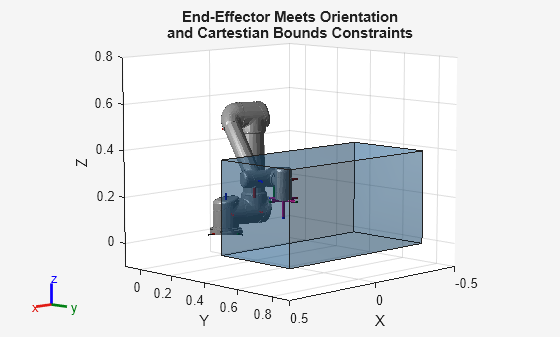

show(robot,config);
title(["End-Effector Meets Orientation","and Cartestian Bounds Constraints"]);
axis([-0.5 0.5 -0.1 0.9 -0.1 0.8])
exampleHelperShowCartesianBounds(cartBnds.Bounds,0.3)
hold off

*Copyright 2024 The MathWorks, Inc.*